clear;
clear clc;
% PHYS 434
% LAB 3
% Jin Kyoung Lee

## Problem 1

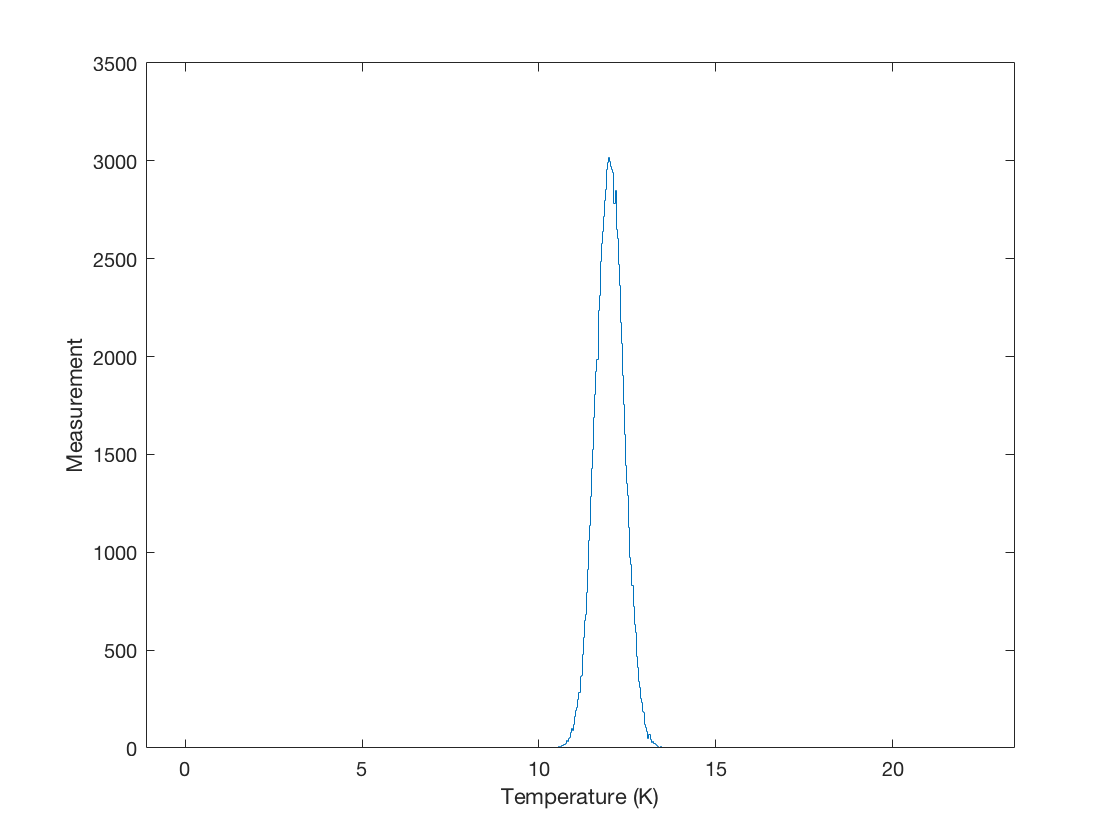

% Temperature should be around 12 Kelvin
% Mean = 12
% Most of data consistent with 12 K to within the 0.4 degree precision of
% the themometry and the thermal control system
% Standard deviation = 0.4

% A)
% 1.
% Creating good 100k data points
goodDP = random('Normal',12,0.4,[1,100000]);
% Bad data points
badDP = [10. 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7];
dataCombined = [goodDP,badDP]; % size: 100k+8 points
% Making plot
histogram(dataCombined,'DisplayStyle','stairs')
xlabel('Temperature (K)')
ylabel('Measurement')

% 2. Statistical question: Goal is to identify bad data and throw it out

% The background will be normal distribution with a mean of 12 and standard
% deviation of 0.4

% Q. What is the threshold for temperature measured from properly working
% thermal control system?

% Reasoning: Since given bad points are all outside of background
% distribution, if we figure out the threshold (5 sigma) for temperature
% measured from properly working thermal control system, we can find the
% data points that are outside of the distribution, and we can assume those
% data points are bad measurement and get rid of them.

% 3. Restate (2) in math.
pdfGoodDP = makedist("Normal","mu",12,"sigma",0.4);
prob5sigma = [1/3.5e6, 1-1/3.5e6];
threshold = icdf(pdfGoodDP,prob5sigma)

threshold =     9.9997   14.0003


% We found out that threshold (5 sigma) is 9.9997 and 14.0003.
% Therefore, if the data points are outside of the range 9.9997<x<14.0003,
% we can assume that those points are bad data points.

% 4. Applying statistical test and construct a truth table
% True Pos = kept good data
% True Neg = mistakes made (omission or commission)
% False Pos = mistakes made (omission or commission)
% False Neg = correctly discarded bad data
minThreshold = threshold(1);
maxThreshold = threshold(2);
dataTest = zeros(100008,1);
for i = 1:100008
    dataTest(i) = dataCombined(i);
    if (dataTest(i)>=minThreshold) && (dataTest(i)<=maxThreshold)
        truePos = dataTest((dataTest>=minThreshold) & (dataTest<=maxThreshold));
        TP = length(truePos);
    else
        (dataTest(i)<minThreshold) || (dataTest(i)>maxThreshold)
        falseNeg = dataTest((dataTest<minThreshold) | (dataTest>maxThreshold));
        FN = length(falseNeg);
    end
end

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


numOfTruePos = TP

numOfTruePos = 100003

numOfFalseNeg = FN

numOfFalseNeg = 6

% B) How does the number of omissions, where you threw out good data depend
% on the statistical threshold you chose and is it a predictable quantity?


% C) Are there mistakes of commission (bad data getting in)? If yes, are
% they avoidable and how do they depend on your statistical threshold?

% Yes. From our given bad data points, three of the bad points got in: 10,
% 10.3, and 12.7. It is because they are within the statistical threshold:
% 9.9997<x<14.0003. With this statistical threshold, it is not possibl to
% avoid that these points get in.

## Problem 2

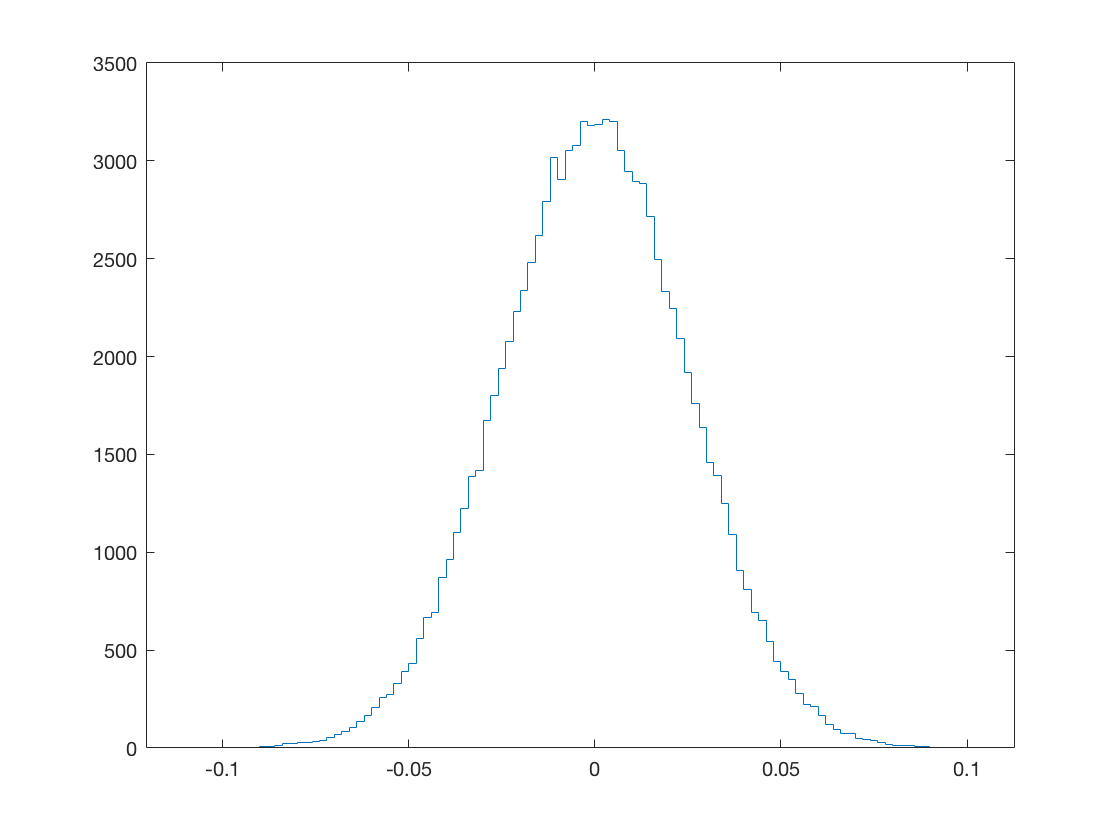

% 2D Gaussian with 1 arcsecond RMS

% 1. Question in words
% What is the distance in arcseconds that have a '5 sigma' detection?

asteroid = random('Normal',0,0.025,[1,100000]);
histogram(asteroid,'DisplayStyle','stairs')

## Problem 3

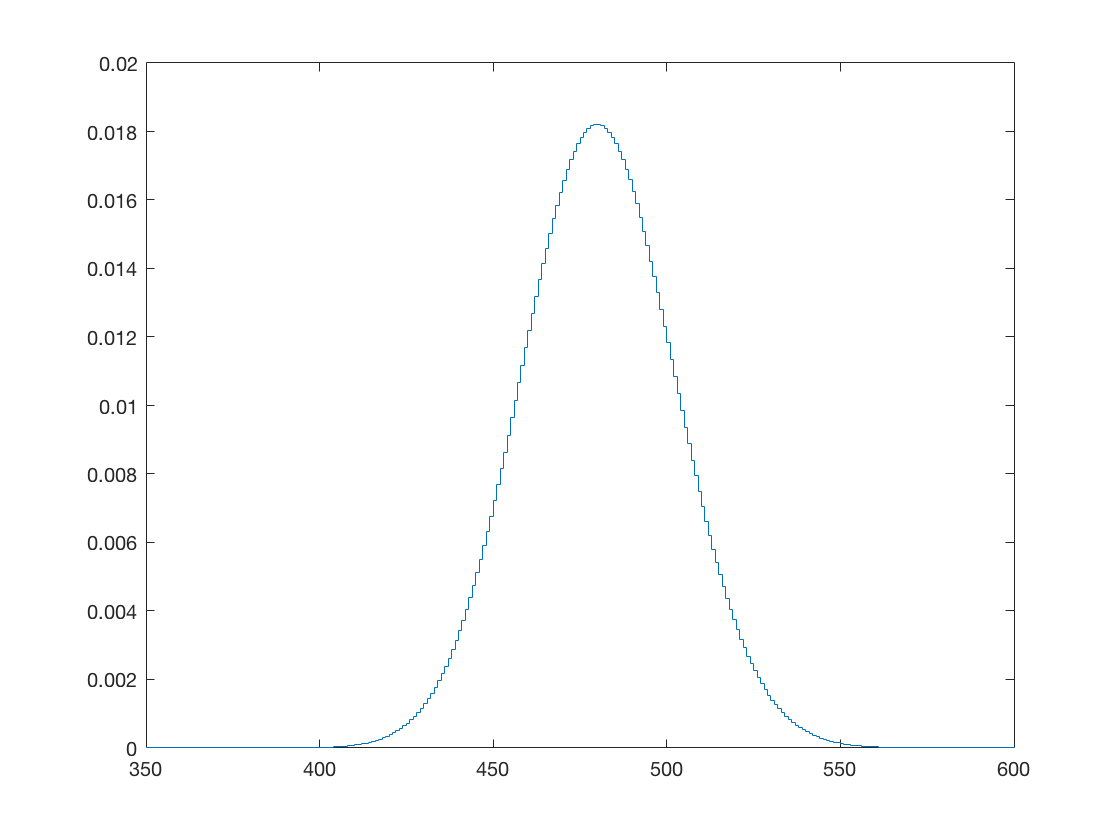

% Cosmic ray rate of 1 cosmic ray/min
% If we can observe where the moon is for 8 hours/night and we observe for
% 15 days and see 6800 cosmic rays, what is the significance of our moon
% shadow detection?

% 8 hours = 480 min
% 1 cosmic ray/min, therefore, 480 cosmic ray/night

% 1) What is pdf for 1 day?
avgBG = 480;
pdf1day = makedist("Poisson","lambda",avgBG);
x3 = 350:600;
stairs(x3,pdf(pdf1day,x3))

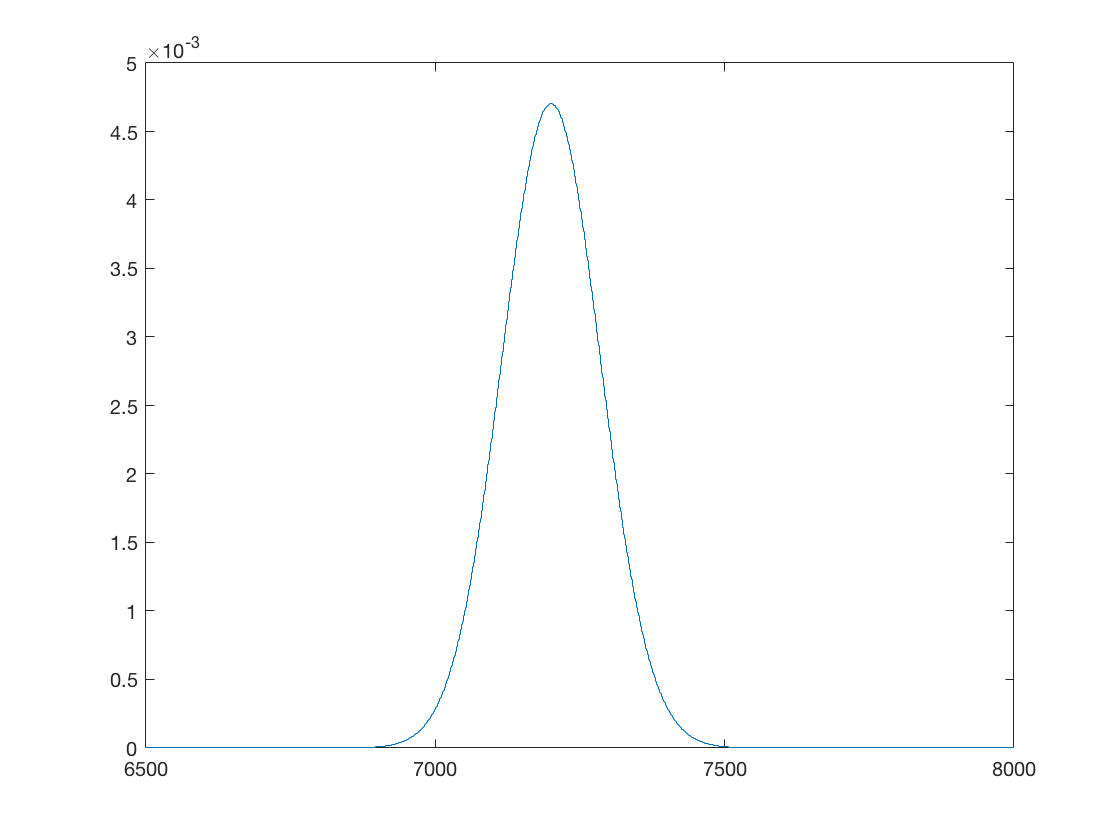

% 2) What is expected probability distribution for 15 days?
numDays = 15;
avgBG15days = avgBG * numDays;
pdf15days = makedist("Poisson","lambda",avgBG15days);
x4 = 6500:8000;
stairs(x4,pdf(pdf15days,x4))

% 3) What is sigma value?
prob6800 = 1 - cdf(pdf15days, 6800)

prob6800 = 1.0000

sigma = icdf("Normal",1-prob6800,0,1)

sigma = -4.7507

% Therefore, the significance of the moon shadow detection is 4 sigma.